# Improvements

## LDA-SVM dimensions

clc
clear
load("MatlabData\trainingData_OG.mat")
load("MatlabData\ValidationData_OG.mat")

remove = [1 9 14 7 2]; %Forward
% remove = [8 1 14 12 9 11 2 10]; %Backward
trainingData(:,remove) = [];
ValidationData(:,remove) = [];
% for i=4:9
for i=1:6
    W_LDA = LDA_Train(trainingData, trainingLabel,i,length(trainingData)/21);
    trainingData_LDA = (W_LDA.' * trainingData.').';
    ValidationData_LDA = (W_LDA.' * ValidationData.').';
    [normalizedData_LDA,centerValue_LDA,scaleValue_LDA] = normalize(trainingData_LDA,"center",...
        "scale");
    trainingData_LDA = normalizedData_LDA;
    ValidationData_LDA = (ValidationData_LDA - centerValue_LDA) ./ scaleValue_LDA;
    
    t = templateSVM('KernelFunction','rbf','KernelScale', 1/(sqrt(0.001)),'BoxConstraint',1000);
    SVMModel = fitcecoc(trainingData_LDA,trainingLabel,"Learners",t,"Coding","onevsone");
    
    predictedLabel = predict(SVMModel, trainingData_LDA);
    writematrix(predictedLabel,append('./Improvements/Improvement_LDA-SVM_', num2str(i), '_train.csv'))
    
    predictedLabel = predict(SVMModel, ValidationData_LDA);
    writematrix(predictedLabel,append('./Improvements/Improvement_LDA-SVM_', num2str(i), '_val.csv'))
end


## More excitation

clc
clear
load("MatlabData\trainingData_OG.mat")

Error using load
'trainingData_OG.mat' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\mikke\Aalborg Universitet\P7 - General\Project\Matlab\Monkey_Test

Change the MATLAB current folder or add its folder to the MATLAB path.

load("MatlabData\ValidationData_OG.mat")
W_LDA = LDA_Train(trainingData, trainingLabel,length(trainingData)/21);
trainingData_LDA = (W_LDA.' * trainingData.').';
ValidationData_LDA = (W_LDA.' * ValidationData.').';
[normalizedData_LDA,centerValue_LDA,scaleValue_LDA] = normalize(trainingData_LDA,"center",...
    "scale");
trainingData_LDA = normalizedData_LDA;
ValidationData_LDA = (ValidationData_LDA - centerValue_LDA) ./ scaleValue_LDA;

t = templateSVM('KernelFunction','rbf','KernelScale', 1/(sqrt(0.0266)),'BoxConstraint',1000);
subplot(2,1,1)
SVMModel = fitcecoc(trainingData_LDA,trainingLabel,"Learners",t,"Coding","onevsone");
predictedLabel = predict(SVMModel, ValidationData_LDA);
Accuracy(predictedLabel,validationLabel.')
cm = confusionchart(validationLabel, predictedLabel);
cm.Normalization = "row-normalized";
cm.Title = 'Confusion Matrix Training Data LDA excited';
writematrix(predictedLabel,'Improvement_Excitation_17.csv')


load("MatlabData\trainingData_OG_12.mat")
load("MatlabData\ValidationData_OG_12.mat")
W_LDA = LDA_Train(trainingData, trainingLabel,6,1200);
trainingData_12_LDA = (W_LDA.' * trainingData.').';
ValidationData_12_LDA = (W_LDA.' * ValidationData.').';
[normalizedData_LDA,centerValue_LDA,scaleValue_LDA] = normalize(trainingData_12_LDA,"center",...
    "scale");
trainingData_12_LDA = normalizedData_LDA;
ValidationData_12_LDA = (ValidationData_12_LDA - centerValue_LDA) ./ scaleValue_LDA;

subplot(2,1,2)
SVMModel = fitcecoc(trainingData_12_LDA,trainingLabel,"Learners",t,"Coding","onevsone");
predictedLabel = predict(SVMModel, ValidationData_12_LDA);
Accuracy(predictedLabel,validationLabel.')
cm = confusionchart(validationLabel, predictedLabel);
cm.Normalization = "row-normalized";
cm.Title = 'Confusion Matrix Validation Data LDA';
writematrix(predictedLabel,'Improvement_Excitation_12.csv') 

## More/Less Data

clc
clear
load("MatlabData\trainingData_OG_improvementData.mat")
load("MatlabData\ValidationData_OG_improvementData.mat")
combinedData = [trainingData_20 ; trainingData_30 ; trainingData_40 ; trainingData_50 ; trainingData_60 ; trainingData_70 ; trainingData_80 ; trainingData_90 ; trainingData_100 ; trainingData_110 ; trainingData_120 ; trainingData_130 ; trainingData_140 ; trainingData_150];
combindedLabel = [trainingLabel_20 , trainingLabel_30 , trainingLabel_40 , trainingLabel_50 , trainingLabel_60 , trainingLabel_70 , trainingLabel_80, trainingLabel_90 , trainingLabel_100 , trainingLabel_110 , trainingLabel_120 , trainingLabel_130 , trainingLabel_140 , trainingLabel_150];
index = [length(trainingLabel_20) ; length(trainingLabel_30) ; length(trainingLabel_40) ; length(trainingLabel_50) ; length(trainingLabel_60) ; length(trainingLabel_70) ; length(trainingLabel_80) ; length(trainingLabel_90) ; length(trainingLabel_100) ; length(trainingLabel_110) ; length(trainingLabel_120) ; length(trainingLabel_130) ; length(trainingLabel_140) ; length(trainingLabel_150)];
startPoint = 1;
for i=1:length(index)
    trainData = combinedData(startPoint:startPoint+index(i)-1,:);
    trainLabel = combindedLabel(startPoint:startPoint+index(i)-1);
    startPoint = startPoint + index(i);

    W_LDA = LDA_Train(trainData, trainLabel, 6, index(i)/21);
    trainData_LDA = (W_LDA.' * trainData.').';
    ValData_LDA = (W_LDA.' * ValidationData.').';
    [normalizedData_LDA,centerValue_LDA,scaleValue_LDA] = normalize(trainData_LDA,"center",...
        "scale");
    trainData_LDA = normalizedData_LDA;
    ValData_LDA = (ValData_LDA - centerValue_LDA) ./ scaleValue_LDA;
    
    t = templateSVM('KernelFunction','rbf','KernelScale', 1/(sqrt(0.0266)),'BoxConstraint',1000);
    SVMModel = fitcecoc(trainData_LDA,trainLabel,"Learners",t,"Coding","onevsone");

    predictedLabel = predict(SVMModel, trainData_LDA);
    acc_train(i) = Accuracy(predictedLabel,trainLabel.');
    predictedLabel = predict(SVMModel, ValData_LDA);
    acc_val(i) = Accuracy(predictedLabel,validationLabel.');
    
%     cm.Title = append('Confusion Matrix for ', num2str(index(i)), ' samples. Acc: ' , num2str(acc));
end
x = linspace(20*17,150*17,length(index));

figure()
plot(x, acc_train, x, acc_val,'LineWidth',1)
title("Accuracy of the classifier with different number of data")
ylabel("Accuracy")
xlabel("Number of samples pr. fault")
legend("Training", "Validation")
xlim([340, 2550])
saveas(gcf,'Images/CompareDataAmount','epsc')

## Feature selection

clc
clear
load("MatlabData\trainingData_OG.mat")
load("MatlabData\ValidationData_OG_smaller.mat")

% Normalize data
[normalizedData_LDA,centerValue_LDA,scaleValue_LDA] = normalize(trainingData,"center",...
    "scale");
trainingData_norm = normalizedData_LDA;
ValidationData_norm = (ValidationData - centerValue_LDA) ./ scaleValue_LDA;

% SVM template
t = templateSVM('KernelFunction','rbf','KernelScale', 1/(sqrt(0.002)),'BoxConstraint',1000);

%%%%Forward selection%%%%

% Initialise variables
acc_train_forw = zeros(14,14);
acc_valid_forw = zeros(14,14);
all_index_forw = [];

for i = 1 : 14
    for n = 1 : 14
        if sum(all_index_forw == n) == 1
            % If feature is already added, set accuracy to 0
            acc_train_forw(i,n) = 0;
        else
            % Add feature numbers to row vector
            add_feat = [all_index_forw n];

            % Train model
            SVMModel = fitcecoc(trainingData_norm(:,add_feat),trainingLabel,"Learners",t,"Coding","onevsone");
            
            % Get accuracies
            predictedLabeltrain = predict(SVMModel,trainingData_norm(:,add_feat));
            acc_train_forw(i,n) = Accuracy(predictedLabeltrain,trainingLabel.');

            predictedLabel = predict(SVMModel,ValidationData_norm(:,add_feat));
            acc_valid_forw(i,n) = Accuracy(predictedLabel,validationLabel.'); 
        end
    end
    % Sort accuracies to get highest value
    [acc_sort, index] = sort(acc_train_forw(i,:), 'descend');

    % Save index of feature number with highest accuracy
    all_index_forw = [all_index_forw index(1)]
end

all_index_forw = 10

all_index_forw =     10     8


all_index_forw =     10     8    11


all_index_forw =     10     8    11    13


all_index_forw =     10     8    11    13     5


all_index_forw =     10     8    11    13     5     6


all_index_forw =     10     8    11    13     5     6     4


all_index_forw =     10     8    11    13     5     6     4    12


all_index_forw =     10     8    11    13     5     6     4    12     3


all_index_forw =     10     8    11    13     5     6     4    12     3     2


all_index_forw =     10     8    11    13     5     6     4    12     3     2     7


all_index_forw =     10     8    11    13     5     6     4    12     3     2     7    14


all_index_forw =     10     8    11    13     5     6     4    12     3     2     7    14     9


all_index_forw =     10     8    11    13     5     6     4    12     3     2     7    14     9     1


save('MatlabData/FeatureForward.mat','all_index_forw','acc_train_forw','acc_valid_forw')

%%%%Backward elimination%%%%

% Initialise variables
acc_train_back = zeros(13,14);
acc_valid_back = zeros(13,14);
all_index_back = [];

for i = 1 : 13
    for n = 1 : 14        
        if sum(all_index_back == n) == 1
            % If feature is already removed, set accuracy to 0
            acc_train_back(i,n) = 0;
        else
            % Remove feature numbers from row vector
            feat = 1:14;
            yeet_feet = [all_index_back n];
            feat(yeet_feet) = [];

            % Train model
            SVMModel = fitcecoc(trainingData_norm(:,feat),trainingLabel,"Learners",t,"Coding","onevsone");
            
            % Get accuracies
            predictedLabeltrain = predict(SVMModel, trainingData_norm(:,feat));
            acc_train_back(i,n) = Accuracy(predictedLabeltrain,trainingLabel.');

            predictedLabel = predict(SVMModel, ValidationData_norm(:,feat));
            acc_valid_back(i,n) = Accuracy(predictedLabel,validationLabel.');
        end

    end
    % Sort accuracies to get highest value
    [acc_sort, index] = sort(acc_train_back(i,:), 'descend');

    % Save index of feature number with highest accuracy
    all_index_back = [all_index_back index(1)]
end

all_index_back = 8

all_index_back =      8     1


all_index_back =      8     1    14


all_index_back =      8     1    14    12


all_index_back =      8     1    14    12     9


all_index_back =      8     1    14    12     9    11


all_index_back =      8     1    14    12     9    11     2


all_index_back =      8     1    14    12     9    11     2    10


all_index_back =      8     1    14    12     9    11     2    10     7


all_index_back =      8     1    14    12     9    11     2    10     7    13


all_index_back =      8     1    14    12     9    11     2    10     7    13     5


all_index_back =      8     1    14    12     9    11     2    10     7    13     5     3


all_index_back =      8     1    14    12     9    11     2    10     7    13     5     3     4


save('MatlabData/FeatureBackward.mat','all_index_back','acc_train_back','acc_valid_back')

%%%%Plot feature selection%%%%
x = linspace(1,14,14);

% Forward selection
acc_for = acc_train_forw(sub2ind(size(acc_train_forw),1:size(acc_train_forw,1),all_index_forw));
acc_for_val = acc_valid_forw(sub2ind(size(acc_valid_forw),1:size(acc_valid_forw,1),all_index_forw));

plot(x, acc_for*100, x, acc_for_val*100,'LineWidth',1)
title('Forward selection')
ylabel("Accuracy [%]")
xlabel("Number of features")
legend({'Training', 'Validation'},'Location','southeast')
xlim([1, 14])
set(gca,'FontSize',18)
% saveas(gcf,'Images/ForwardSelection','epsc')

% Backward elimination
acc_bac = acc_train_back(sub2ind(size(acc_train_back),1:size(acc_train_back,1),all_index_back));
acc_bac = [flip(acc_bac) acc_for(14)]

acc_bac =     0.1111    0.2270    0.6467    0.8345    0.8884    0.8975    0.9040    0.9050    0.9089    0.9091    0.9088    0.9103    0.9080    0.9073


% Add last feature for backward
acc_bac_val = acc_valid_back(sub2ind(size(acc_valid_back),1:size(acc_valid_back,1),all_index_back));
acc_bac_val = [flip(acc_bac_val) acc_for_val(14)]

acc_bac_val =     0.0952    0.1905    0.4762    0.8571    0.9048    0.9048    0.8571    0.8571    0.8571    0.8571    0.8571    0.8571    0.8571    0.8571


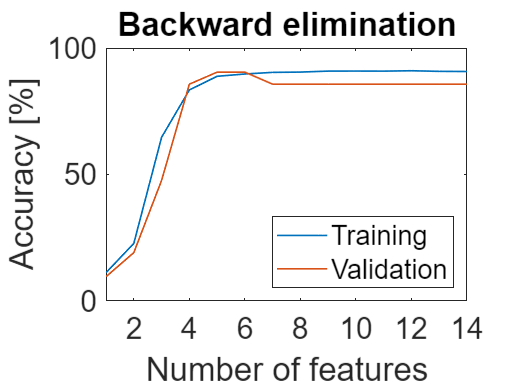


plot(x, acc_bac*100, x, acc_bac_val*100,'LineWidth',1)
title('Backward elimination')
ylabel("Accuracy [%]")
xlabel("Number of features")
legend({'Training ', 'Validation'},'Location','southeast')
xlim([1, 14])
set(gca,'FontSize',18)
% saveas(gcf,'Images/BackwardElimination','epsc')

function W = LDA_Train(data, label, D, Nk)
    % Calculate mean of each class
    for i=1:21
        mu(i,:)= mean(data(label == i,:));
    end
    % Calculate total mean
    mu(22,:) = mean(data);

    % Calculate within-class scattesr
    Sw = 0;
    for j=1:size(mu,1)-1
        Sw = Sw + (data(find(label==j),:)' - mu(j,:)') * (data(find(label==j),:)' - mu(j,:)')';
    end
    % Calculate between-class scatter
    Sb = Nk .* (mu(1:21,:)' - mu(22,:)') * (mu(1:21,:)' - mu(22,:)')';

    % Use the eigenvalue decomposition and sort it in decending order
    [V e] = eig(Sb,Sw);
    [B,I] = sort(diag(e),'descend');

    % Take D number of eigenvectores corresponding to the largest values
    for i=1:D
        W(:,i) = V(:,I(i));
    end
end
function acc = Accuracy(predicted, true)
    [Ntst sz]= size(predicted);
    % Number of correct classifications
    correct = sum(predicted == true);
    % Accuracy
    acc = correct/Ntst;
end